## Assignment Section

**윤지상_2019092115**

### Exercise 1: Hand Made Inverse Algorithm

% ■ Implement the full-inverse algorithm for a 2 × 2 matrix using matrix elements 𝑎, 𝑏, 𝑐,
%   and 𝑑. (not using inverse function)
% ■ Hint: Remember that the determinant of a scalar is its absolute value.

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Assume that input value is [a,b;c,d] (2x2 matrix)
% then make a function that return a inverse matrix
% NOTE: Do not use inverse function in MATLAB

% input1
a1 = 2;
b1 = 1;
c1 = 6;
d1 = 8;

% input2
a2 = 4;
b2 = 10;
c2 = 2;
d2 = 5;

% Write here (start)
% Create error when inverse matrix does not exist
function inverse_matrix = handMadeInverseMatrix(a, b, c, d)
    % Compute the determinant
    origin_m = [a b; 
                c d];
    det_m = det(origin_m);
    adj_m = [d -b; 
             -c a];
    % Check error
    if det_m == 0
        error('Matrix is not invertible');
    end
    
    % Compute the inverse manually
    inverse_matrix = (1/det_m) * adj_m;
    % inverse_matrix = inv(origin_m);

end
% Write here (end)

% Call the function and store the inverse matrix
% Display the result
inv1 = handMadeInverseMatrix(a1,b1,c1,d1);
disp('Inverse matrix1:');

Inverse matrix1:


disp(inv1);

    0.8000   -0.1000
   -0.6000    0.2000



inv2 = handMadeInverseMatrix(a2,b2,c2,d2);

Error using Exercise_08_2019092115>handMadeInverseMatrix (line 35)
Matrix is not invertible

### Exercise 2: Implements of Various Matrices

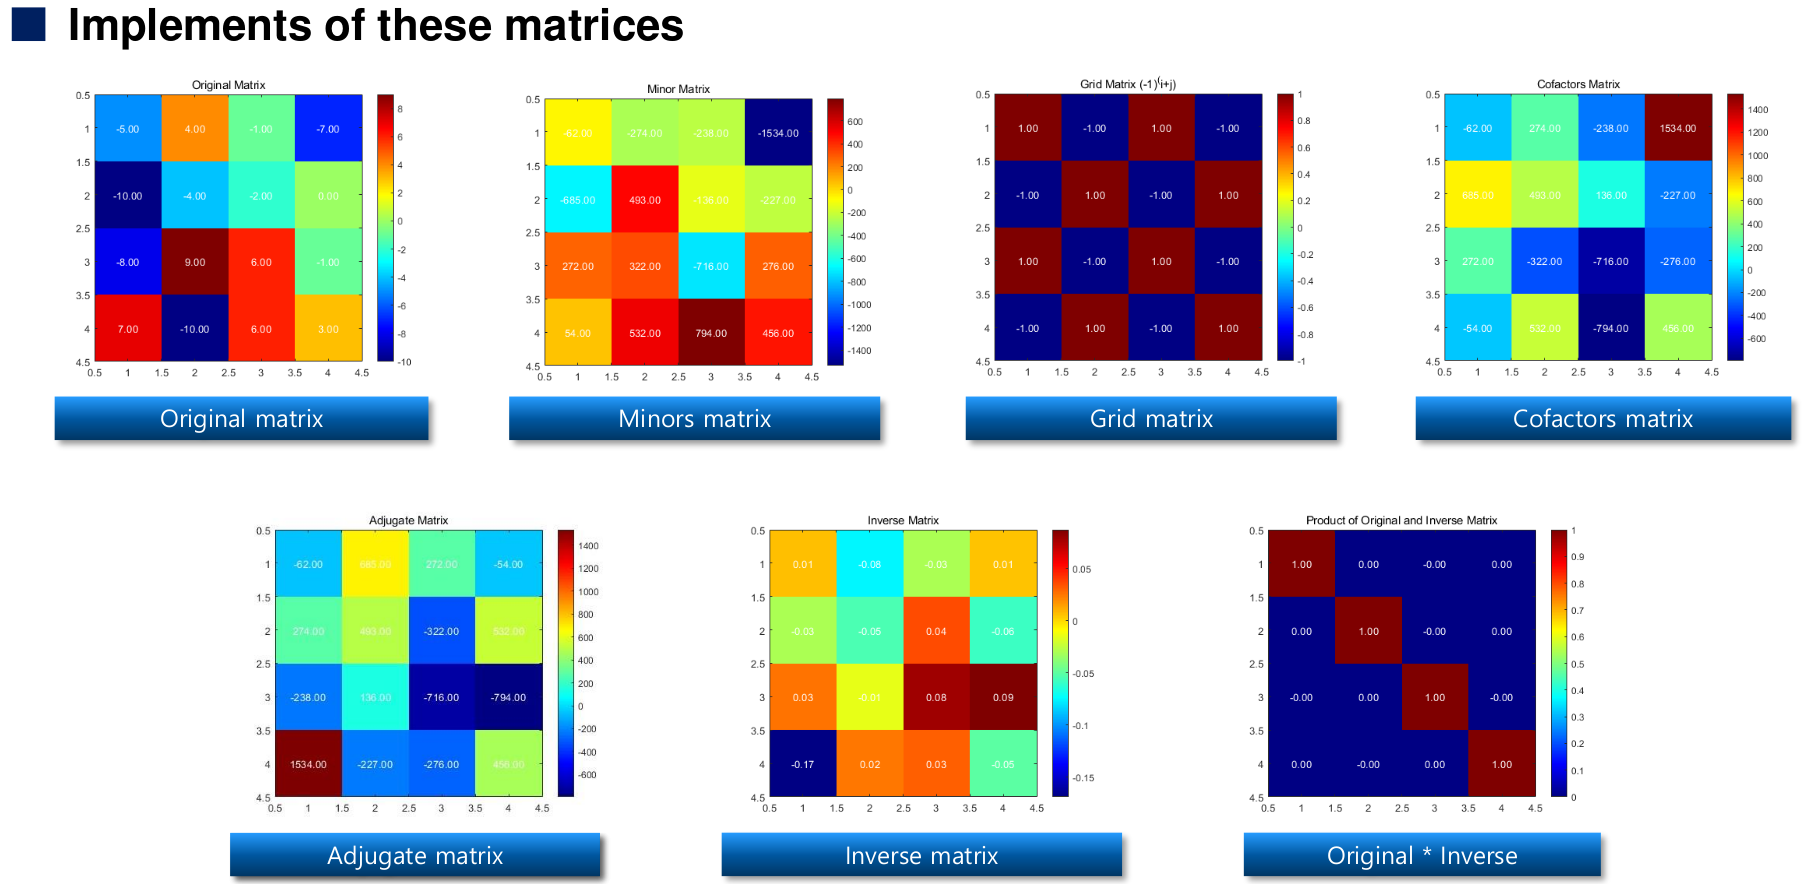

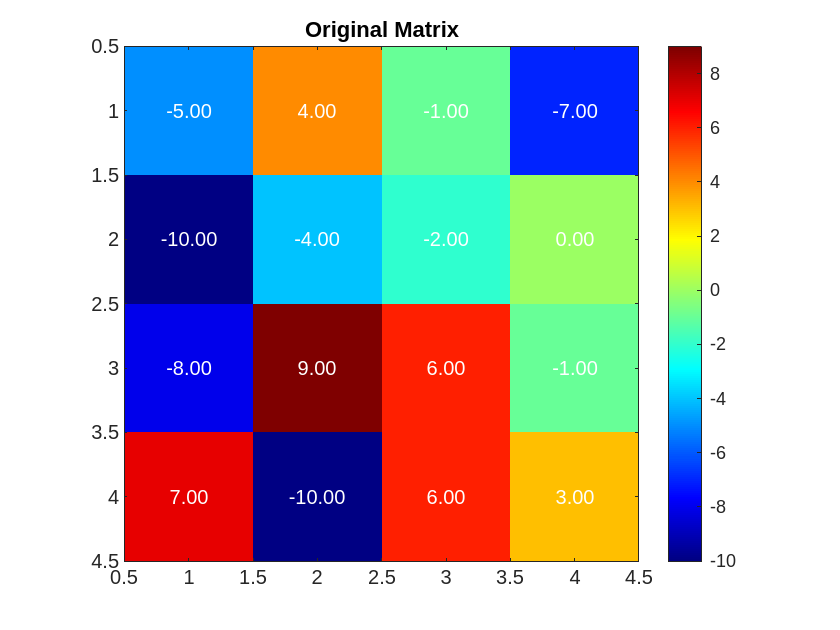

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Create a 4x4 original matrix with integer elements
originalMatrix = [-5,4,-1,-7;
                  -10,-4,-2,0;
                  -8,9,6,-1;
                  7,-10,6,3];

% Create a 4x4 grid matrix where elements are (-1)^(i+j)
[i, j] = meshgrid(1:4, 1:4);
gridMatrix = (-1).^(i+j);

% Compute the minor matrix
minorMatrix = zeros(4);
for row = 1:4
    for col = 1:4
        subMatrix = originalMatrix;
        subMatrix(row, :) = [];
        subMatrix(:, col) = [];
        minorMatrix(row, col) = det(subMatrix);
    end
end

% Write here (start)
% Refer to the lecture slide 43
% Compute the cofactors matrix
% Use '.*' function to compute the cofactorsMatrix
cofactorsMatrix = gridMatrix .* minorMatrix;

% Check if the matrix is invertible
determinant = det(originalMatrix);
if determinant == 0
    error('The original matrix is singular and does not have an inverse.');
end

% Compute the adjugate matrix and inverse matrix of the original matrix
% Use 'transpose(matrix)' to compute the adjugate matrix
% Use adjugateMatrix to compute inverse matrix
adjugateMatrix = cofactorsMatrix';
inverseMatrix = (1/determinant) * adjugateMatrix;

% Compute the product of the original matrix and its inverse
identityMatrix = inverseMatrix * originalMatrix;
% Write here (end)

% Visualize all matrices
visualizeMatrix(originalMatrix, 'Original Matrix');

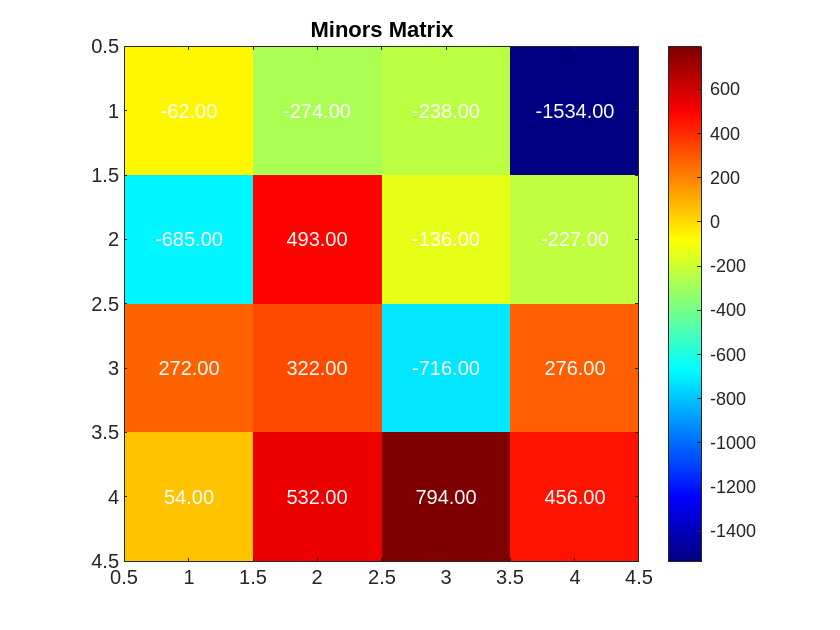

visualizeMatrix(minorMatrix, 'Minors Matrix');

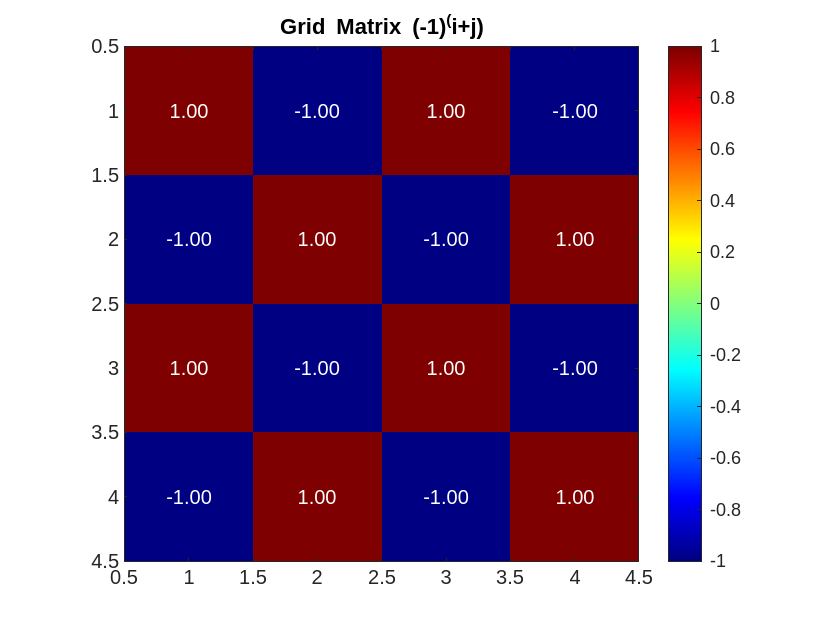

visualizeMatrix(gridMatrix, 'Grid Matrix (-1)^(i+j)');

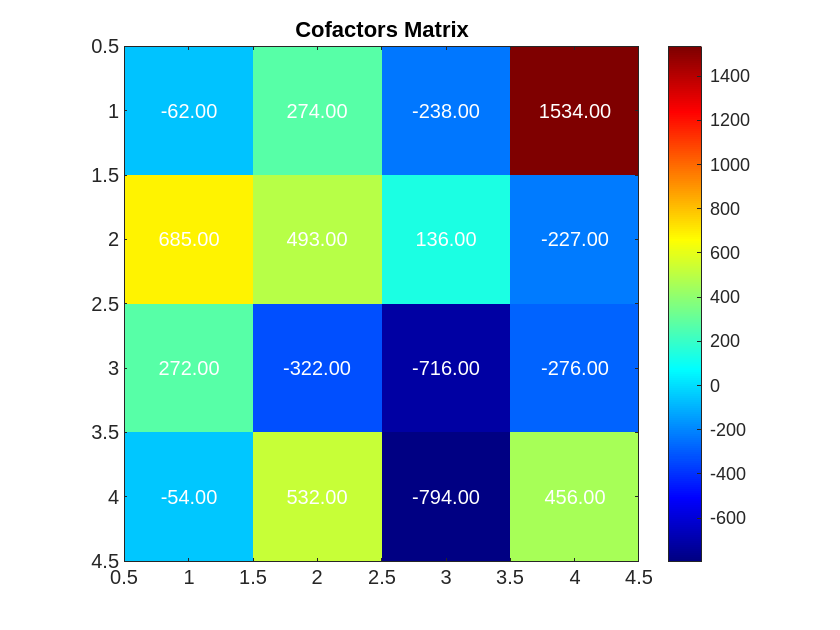

visualizeMatrix(cofactorsMatrix, 'Cofactors Matrix');

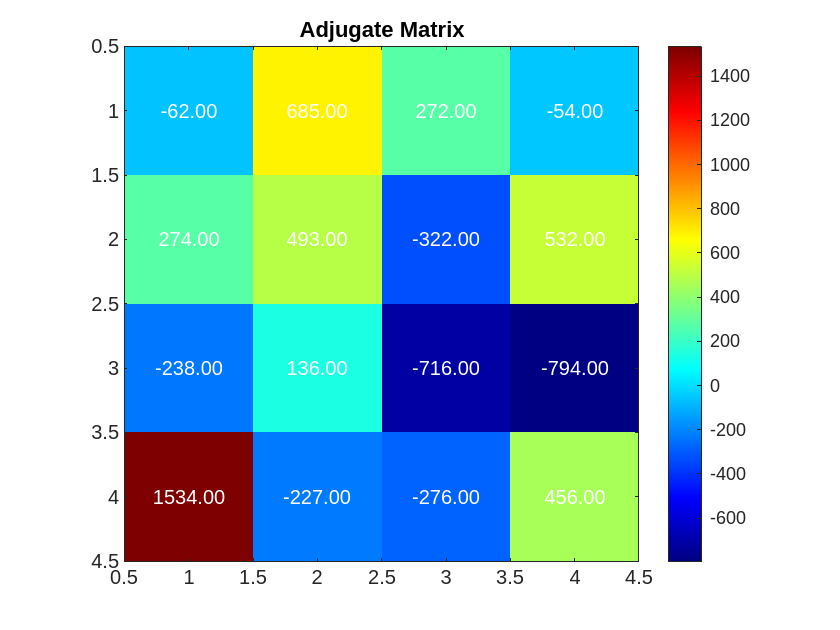

visualizeMatrix(adjugateMatrix, 'Adjugate Matrix');

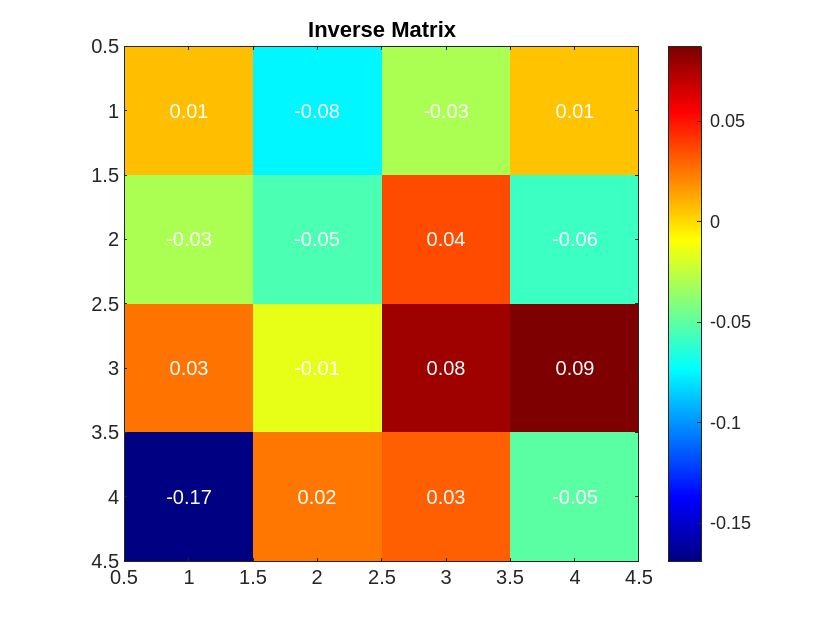

visualizeMatrix(inverseMatrix, 'Inverse Matrix');

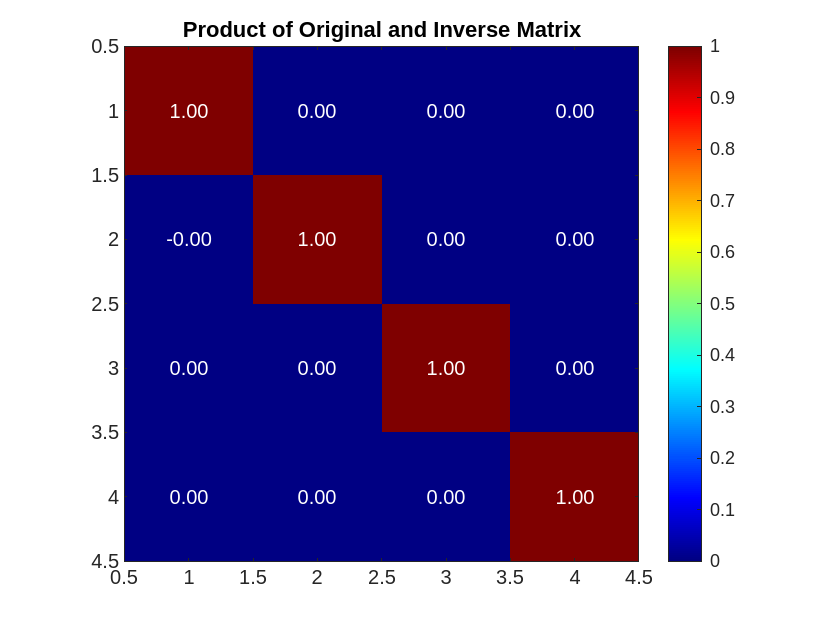

visualizeMatrix(identityMatrix, 'Product of Original and Inverse Matrix');


% Function definition : visualize matrix
function visualizeMatrix(matrix, titleStr)
    figure;
    imagesc(matrix);
    colorbar;
    title(titleStr);
    colormap jet;
    axis square;
    % Add text annotations for each element
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            text(j, i, num2str(matrix(i, j), '%.2f'), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'white', 'FontSize', 10);
        end
    end
end